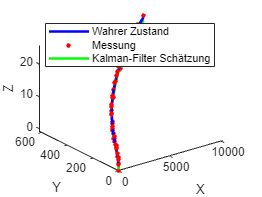

% Parameter des Systems
dt = 1;                % Abtastzeit
A = [1 dt dt^2/2; 0 1 dt; 0 0 1];       % Zustandsübergangsmatrix
B = [dt^3/6; dt^2/2; dt];      % Steuerungsmatrix (Beschleunigung)
C = eye(3);             % Messmatrix (direkte Messung von X, Y, Z)
Q = diag([0.01, 0.01, 0.1]);   % Prozessrauschkovarianz
R = diag([1, 1, 1]);                 % Messrauschkovarianz

% Simulierte Daten
T = 50;               % Anzahl der Zeitschritte
true_pos = zeros(3, T);
measured_pos = zeros(3, T);
velocity = [1; 0; 0];      % Geschwindigkeitsvektor (konstant in x-Richtung)
acceleration = [0; 0; 0.5]; % Beschleunigungsvektor (konstant in z-Richtung)
for t = 1:T
    true_pos(:,t) = A * (true_pos(:, max(t-1,1))) + B .* acceleration;    % Zustandsübergang
    measured_pos(:,t) = true_pos(:,t) + sqrt(R) * randn(3, 1);        % Messung
end

% Initialisierung
x = zeros(3, T);       % Zustandsschätzung
P = zeros(3, 3, T);    % Zustandskovarianzschätzung

% Schätzung mit Kalman-Filter
for t = 1:T
    % Vorhersage
    if t == 1
        x_pred = [0; 0; 0];
        P_pred = eye(3);
    else
        x_pred = A * x(:,t-1);
        P_pred = A * P(:,:,t-1) * A' + Q;
    end
    
    % Korrektur
    K = P_pred * C' / (C * P_pred * C' + R);
    x(:,t) = x_pred + K * (measured_pos(:,t) - C * x_pred);
    P(:,:,t) = (eye(3) - K * C) * P_pred;
end

% Ergebnisse anzeigen
figure;
hold on;
plot3(true_pos(1,:), true_pos(2,:), true_pos(3,:), 'b-', 'LineWidth', 2);
plot3(measured_pos(1,:), measured_pos(2,:), measured_pos(3,:), 'r.', 'MarkerSize', 10);
plot3(x(1,:), x(2,:), x(3,:), 'g-', 'LineWidth', 2);
legend('Wahrer Zustand', 'Messung', 'Kalman-Filter Schätzung');
xlabel('X');
ylabel('Y');
zlabel('Z');
view(3);

R_0 = [0; 0; 0];  % Anfangsposition (Nullvektor)
V_0 = [0; 0; 0];  % Anfangsgeschwindigkeit (Nullvektor)
t = linspace(0, 120, 240); % Zeitbereich auf eine Minute erweitert

% A ist eine Matrix, die die Beschleunigung in x-, y- und z-Richtung in Abhängigkeit von der Zeit t enthält.
% Die Beschleunigung wird durch trigonometrische Funktionen erzeugt.
A = [1 * cos(t/12); 0.5 * sin(t/12); 0.05 * ones(size(t/12))]; 

% V ist eine Matrix, die die Geschwindigkeit in x-, y- und z-Richtung in Abhängigkeit von der Zeit t enthält.
% Die Geschwindigkeit wird durch numerische Integration der Beschleunigung berechnet.
% Die Anfangsgeschwindigkeit V_0 wird hinzugefügt.
V = cumtrapz(t/12, A, 2) + V_0;


% R ist eine Matrix, die die Position in x-, y- und z-Richtung in Abhängigkeit von der Zeit t enthält.
% Die Position wird durch numerische Integration der Geschwindigkeit und Beschleunigung berechnet.
% Der Anfangsposition R_0 und zusätzlichen Ausdrücken für die Berücksichtigung der Beschleunigung während der Bewegung wird hinzugefügt.
R = R_0 + cumtrapz(t/12, V, 2) + 0.5 * cumtrapz(t/12, A, 2) .* t;

pos_radar1 = [0, -10, 0];  % Position des Radar 1: x=0, y=-10, z=0
pos_radar2 = [-50, 30, 0];  % Position des Radar 2: x=-50, y=30, z=0


R_transposed = transpose(R);  % Transponiert die Matrix R

dist_matrix_radar1 = [];
dist_matrix_radar2 = [];

dist_3dmatrix_radar1 = [];
dist_3dmatrix_radar2 = [];

for i = 1:length(R_transposed)
    
    %Berechnung des Absoluten Abstand im 3D-Raum
    dist_radar1 = norm(R_transposed(i, :) - pos_radar1);  % Berechnet den Abstand zwischen der i-ten Zeile von R_transposed und pos_radar1
    dist_radar2 = norm(R_transposed(i, :) - pos_radar2);  % Berechnet den Abstand zwischen der i-ten Zeile von R_transposed und pos_radar2
    
    dist_matrix_radar1 = [dist_matrix_radar1; dist_radar1];  % Fügt den Abstand dist_radar1 der dist_matrix_radar1 hinzu
    dist_matrix_radar2 = [dist_matrix_radar2; dist_radar2];  % Fügt den Abstand dist_radar2 der dist_matrix_radar2 hinzu
    
    %Berechnung des Abstands seperat in x,y,z Richtung
    dist3d_radar1 = [R(1,i)-pos_radar1(1), R(2,i)-pos_radar1(2), R(3,i)-pos_radar1(3)];  % Berechnet den 3D-Abstand zwischen R(:,i) und pos_radar1
    dist3d_radar2 = [R(1,i)-pos_radar2(1), R(2,i)-pos_radar2(2), R(3,i)-pos_radar2(3)];  % Berechnet den 3D-Abstand zwischen R(:,i) und pos_radar2
    
    dist_3dmatrix_radar1 = [dist_3dmatrix_radar1; dist3d_radar1];  % Fügt den 3D-Abstand dist3d_radar1 der dist_3dmatrix_radar1 hinzu
    dist_3dmatrix_radar2 = [dist_3dmatrix_radar2; dist3d_radar2];  % Fügt den 3D-Abstand dist3d_radar2 der dist_3dmatrix_radar2 hinzu

end

dist_matrix_radar1  % Gibt die dist_matrix_radar1 aus
dist_matrix_radar2  % Gibt die dist_matrix_radar2 aus

dist_3dmatrix_radar1  % Gibt die dist_3dmatrix_radar1 aus
dist_3dmatrix_radar2  % Gibt die dist_3dmatrix_radar2 aus


alpha_vertikal_radar1 = [];  % Leerer Vektor für die vertikalen Winkel von Radar 1
alpha_vertikal_radar2 = [];  % Leerer Vektor für die vertikalen Winkel von Radar 2

alpha_horizontal_radar1 = [];  % Leerer Vektor für die horizontalen Winkel von Radar 1
alpha_horizontal_radar2 = [];  % Leerer Vektor für die horizontalen Winkel von Radar 2

for i = 1:length(R_transposed)
    
    % Berechnung des Winkels nach oben (vertikal) von Radar 1
    delta_z = R_transposed(i,3) - pos_radar1(3);
    delta_y = R_transposed(i,2) - pos_radar1(2);
    alpha_vertikal_radar1 = [alpha_vertikal_radar1; rad2deg(atan(delta_z/delta_y))];  % Fügt den Winkel zu alpha_vertikal_radar1 hinzu
    
    % Berechnung des Winkels nach oben (vertikal) von Radar 2
    delta_z = R_transposed(i,3) - pos_radar2(3);
    delta_x = R_transposed(i,1) - pos_radar2(1);
    alpha_vertikal_radar2 = [alpha_vertikal_radar2; rad2deg(atan(delta_z/delta_x))];  % Fügt den Winkel zu alpha_vertikal_radar2 hinzu
    
    
    % Berechnung des Winkels nach rechts und links (horizontal) von Radar 1
    delta_x = R_transposed(i,1) - pos_radar1(1);
    delta_y = R_transposed(i,2) - pos_radar1(2);
    alpha_horizontal_radar1 = [alpha_horizontal_radar1; rad2deg(atan(delta_x/delta_y))];  % Fügt den Winkel zu alpha_horizontal_radar1 hinzu
    
    % Berechnung des Winkels nach rechts und links (horizontal) von Radar 2
    delta_y = R_transposed(i,2) - pos_radar2(2);
    delta_x = R_transposed(i,1) - pos_radar2(1);
    alpha_horizontal_radar2 = [alpha_horizontal_radar2; rad2deg(atan(delta_y/delta_x))];  % Fügt den Winkel zu alpha_horizontal_radar2 hinzu   
end

alpha_vertikal_radar1  % Gibt die vertikalen Winkel von Radar 1 aus
alpha_vertikal_radar2  % Gibt die vertikalen Winkel von Radar 2 aus

alpha_horizontal_radar1  % Gibt die horizontalen Winkel von Radar 1 aus
alpha_horizontal_radar2  % Gibt die horizontalen Winkel von Radar 2 aus
